# Investigating Compartmental Systems - Plots (180497C)

## PART 1 - Question 01

a). When A(t) = 1g/kg/h

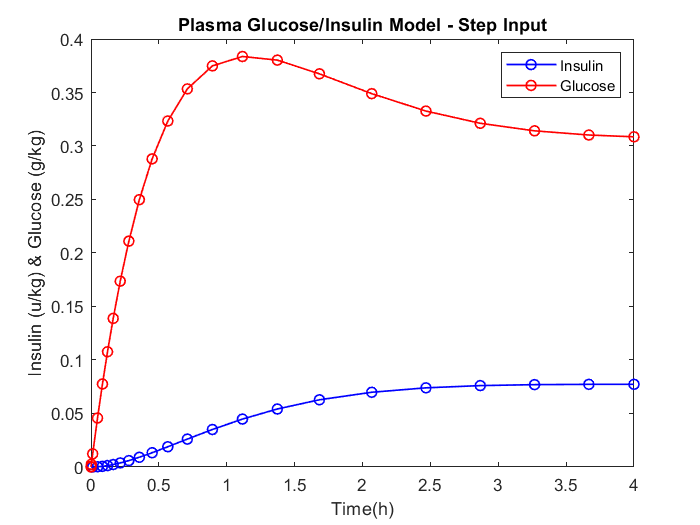

[t,y] = ode23('G_I_StepInput', [0 4], [0 0]);
plot(t, y(:,1),'b-o','LineWidth',1)
hold on
plot(t, y(:,2), 'r-o','LineWidth',1)
hold off
xlabel('Time(h)')
ylabel('Insulin (u/kg) & Glucose (g/kg)')
title('Plasma Glucose/Insulin Model - Step Input')
legend('Insulin','Glucose')

b). When A(t) = 1 - sign(t) g/kg/h

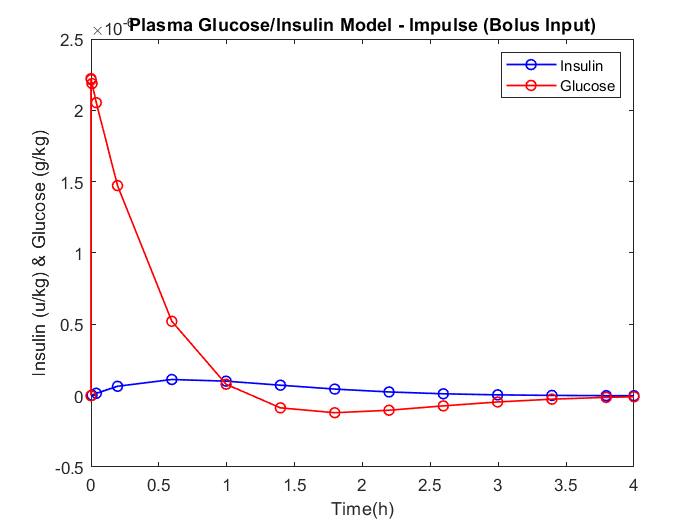

[t,y] = ode23('G_I_Impulse', [0 4], [0 0]);
plot(t, y(:,1),'b-o','LineWidth',1)
hold on
plot(t, y(:,2), 'r-o','LineWidth',1)
hold off
xlabel('Time(h)')
ylabel('Insulin (u/kg) & Glucose (g/kg)')
title('Plasma Glucose/Insulin Model - Impulse (Bolus Input)')
legend('Insulin','Glucose')

c). Diabetic patient

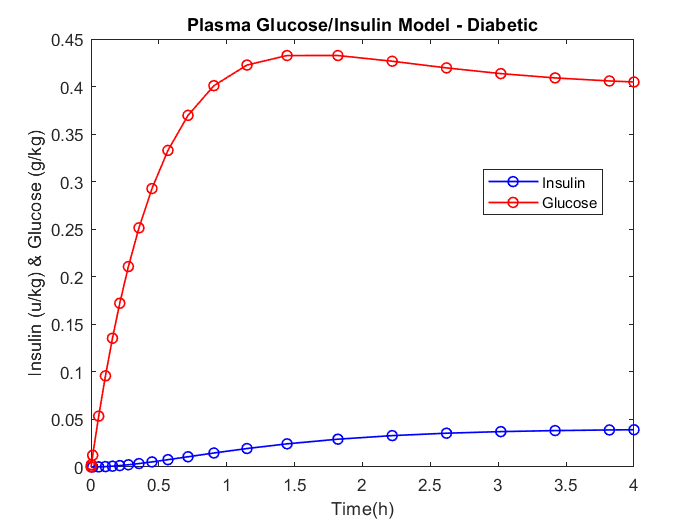

[t,y] = ode23('G_I_Diabetic', [0 4], [0 0]);
plot(t, y(:,1),'b-o','LineWidth',1)
hold on
plot(t, y(:,2), 'r-o','LineWidth',1)
hold off
xlabel('Time(h)')
ylabel('Insulin (u/kg) & Glucose (g/kg)')
title('Plasma Glucose/Insulin Model - Diabetic')
legend('Insulin','Glucose','Location','best')

d). Diabetic patient with insulin infusion of 100mU/kg/h

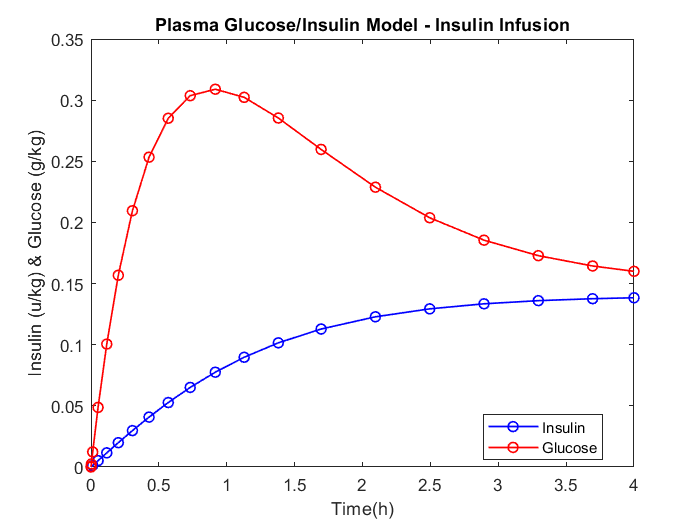

[t,y] = ode23('G_I_Insulin_Infusion', [0 4], [0 0]);
plot(t, y(:,1),'b-o','LineWidth',1)
hold on
plot(t, y(:,2), 'r-o','LineWidth',1)
hold off
xlabel('Time(h)')
ylabel('Insulin (u/kg) & Glucose (g/kg)')
title('Plasma Glucose/Insulin Model - Insulin Infusion')
legend('Insulin','Glucose','Location','best')